# Problem 5

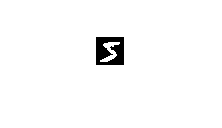

%%% Loading 60000 training set and labels %%%
data = load('../data/mnist.mat');
images = getfield(data,'digits_train');
float_images = cast(images,'double');
labels = getfield(data,'labels_train');

%%% Visuallisation of images %%%
imshow(float_images(:,:,1));

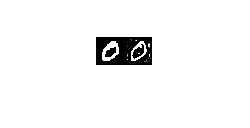

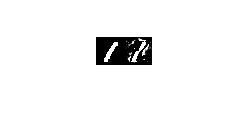

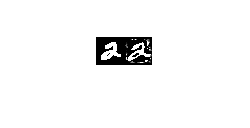

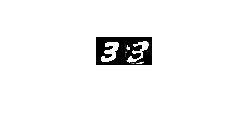

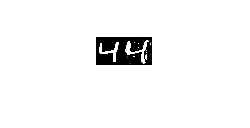

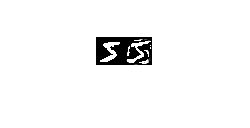

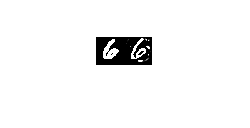

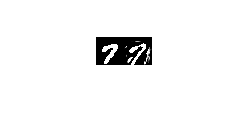

% isfloat(float_images);

for i = 0:9
    image_indices = find(labels==i);
    images = float_images(:,:,image_indices);
    ndim_images = pca_inverse_transform(images,84);
    figure
    img = imshow([images(:,:,1) ndim_images(:,:,1)]);
    drawnow
    saveas(img,string(i),'jpg');
end

Algorithmn for regenerating/reconstructing the image

function y = pca_inverse_transform(images,n)
    dim = size(images);
    freq = dim(3);
    imgvec = reshape(images,dim(1)*dim(1),1,freq);
    
    mean = sum(imgvec,3)/freq;
    imgvec_centered = imgvec - mean;
    
    covariance = zeros(28*28,28*28,'double');
    for j = 1:freq
        covariance = covariance + imgvec_centered(:,:,j)*imgvec_centered(:,:,j).';
    end
    covariance = covariance/freq - mean*mean.';
    
    [Q,D] = eig(covariance);
    [~,ind] = sort(diag(D),'descend');
    ind = ind(1:n);
    U = Q(:,ind);
    
    Y = U.'*squeeze(imgvec);
    y = reshape(U*Y,dim(1),dim(1),freq);
end

Function to compute 84-dimensional basis

function y = pca_transform(images,n)
    dim = size(images);
    freq = dim(3);
    imgvec = reshape(images,dim(1)*dim(1),1,freq);
    
    mean = sum(imgvec,3)/freq;
    imgvec_centered = imgvec - mean;
    
    covariance = zeros(28*28,28*28);
    for j = 1:freq
        covariance = covariance + imgvec_centered(:,:,j)*imgvec_centered(:,:,j).';
    end
    covariance = covariance/freq - mean*mean.';
    
    [Q,D] = eig(covariance);
    [~,ind] = sort(diag(D),'descend');
    ind = ind(1:n);
    U = Q(:,ind);
    
    Y = U.'*squeeze(imgvec);
    y = reshape(Y,n,1,freq);
end